# Generating, Loading and Filtering Signals

## Generating signal and finding peaks

Consider the following signal: x(t) = 5 sin(2π5t) + 3 cos(2π7t) .

 Write a Matlab program to do the following: 

- Generate a sampled version of the signal at the sampling frequency fs = 100 Hz for the duration of 0 − 10 seconds.

-  Write a Matlab function to find all the peaks and troughs or valleys (positive and negative) in the sampled signal. A sample represents a peak or trough (or valley) if the preceding and the subsequent samples are lower in magnitude than the sample under consideration. 

Consider the signal x(t)

x = @(t) (5.*sin(2.*pi.*5.*t) + 3.*cos(2.*pi.*7.*t));

#### 1. Sampling a continuous signal

fs = 100; % Sampling rate (Hz)
T = 10;  % Total period (s)
n = 1:1/fs:T;
data = arrayfun(x,n);

#### 2. Detecting signal peaks and troughs

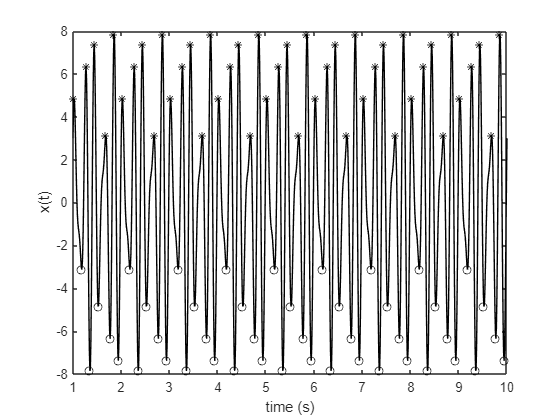

% Find all the peaks in the sample
[peaks,plocations] = findpeaks(data,n); 


% Find all the troughs in the sample
[troughs,tlocations] = findpeaks( -1.*data,n);
troughs = -1.*troughs;

% Plot both peaks as '*' and troughs as 'o' on top of the sampled signal
figure;
plot(n, data, 'k-'); hold on;
plot(plocations, peaks, 'k*');
plot(tlocations, troughs, 'ko');
hold off; 
xlabel('time (s)');
ylabel('x(t)');

## Filtering sinevawe signal

### Generating the signal

Generate the sum of sinusoids for duration of 1 second:$x\left(t\right)=5\cos \left(2\pi \left(500\right)t\right)+5\cos \left(2\pi \left(1200\right)t+0\ldotp 25\pi \right)+5\cos \left(2\pi \left(1800\right)t+0\ldotp 5\pi \right)$ using a sampling rate of 8 kHz.

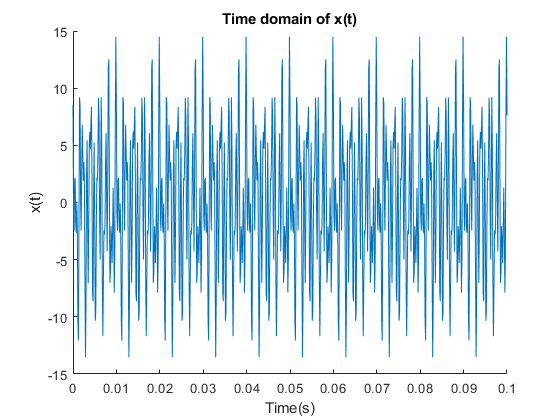

t = 0:1.25e-4:1; % fs=8000Hz -> Ts=1.25x10^-4
xt = 5*cos(2*pi*500*t) + 5*cos(2*pi*1200*t + 0.25*pi) + 5*cos(2*pi*1800*t + 0.5*pi);
figure
hold on
plot(t,xt);
axis([0 0.1 -15 15]);
xlabel('Time(s)');
ylabel('x(t)');
title('Time domain of x(t)');
hold off

###    Fourier transform

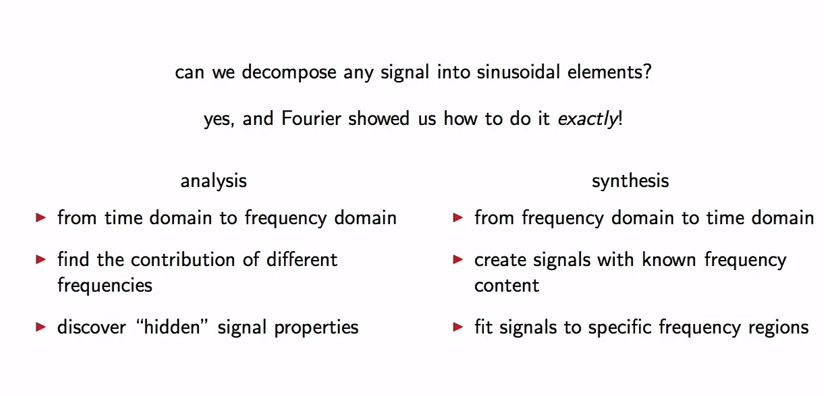

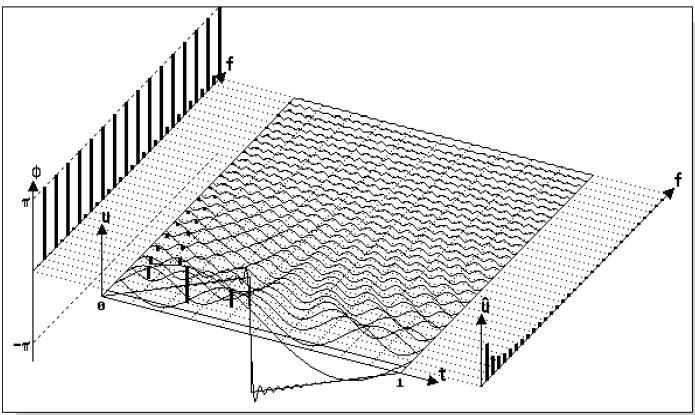

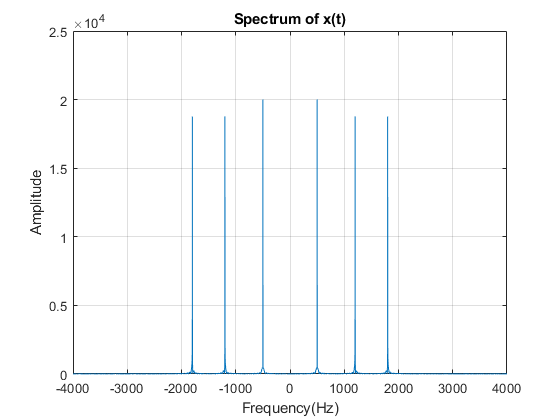

fs = 8e3;
N = nextpow2(length(xt));
X = fftshift(fft(xt,2^N));
%X = 2* X / length(xt);
k = -(length(X)-1)/2:1:length(X)/2;
f = k/length(X) * fs;
figure;
plot(f,abs(X));
grid;
xlabel('Frequency(Hz)');
ylabel('Amplitude');
title('Spectrum of x(t)');

### Filtering the signal

Write MATLAB programs using the MATLAB function **filter()** according to the two given FIR systems.

a. Perform digital filtering using each of the developed programs, plot the input signal spectrum and the output signal spectrum using the frequency resolution of 1 Hz, respectively. Print and label the spectrum. What frequency components/component (frequency locations of the spectral peak(s)) are/is shown in the output signal spectrum?

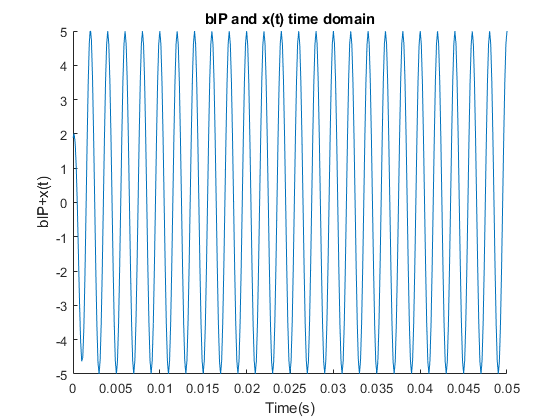

y1t=lowpass(xt,500,fs); 
figure
hold on
plot(t,y1t);
axis([0 0.05 -5 5]);
xlabel('Time(s)');
ylabel('blP+x(t)');
title('blP and x(t) time domain');
hold off

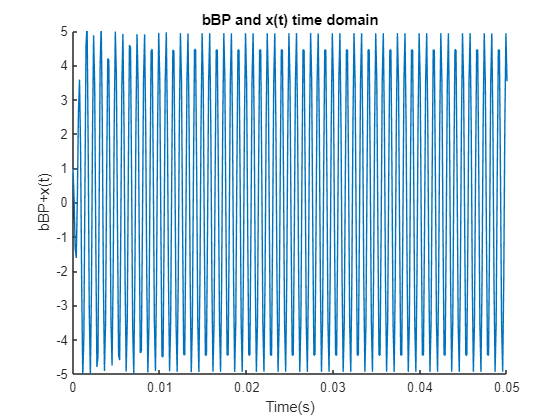

y2t=bandpass(xt, [700, 1400], fs);
figure
hold on
plot(t,y2t);
axis([0 0.05 -5 5]);
xlabel('Time(s)');
ylabel('bBP+x(t)');
title('bBP and x(t) time domain');
hold off

b. Listen to and compare the input signal and output signal from each filter, respectively. Discuss the obtained results.

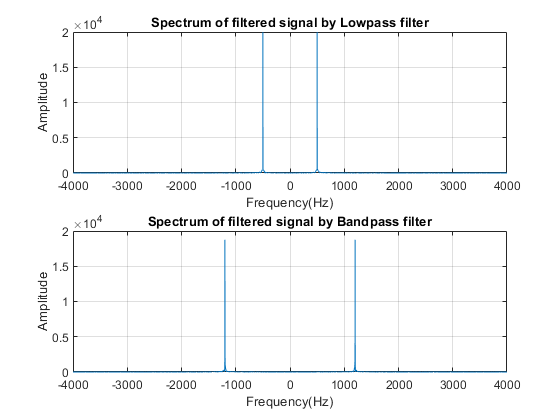

N = nextpow2(length(y1t));
X = fftshift(fft(y1t,2^N));
%X = 2* X / length(y1t);
k = -(length(X)-1)/2:1:length(X)/2;
f = k/length(X) * fs;
subplot(211);
plot(f,abs(X));
grid;
xlabel('Frequency(Hz)');ylabel('Amplitude');
title('Spectrum of filtered signal by Lowpass filter');
N = nextpow2(length(y2t));
X = fftshift(fft(y2t,2^N));
%X = 2* X / length(y2t);
k = -(length(X)-1)/2:1:length(X)/2;
f = k/length(X) * fs;
subplot(212);
plot(f,abs(X));
grid;
xlabel('Frequency(Hz)');ylabel('Amplitude');
title('Spectrum of filtered signal by Bandpass filter');

The first filter allowed 500Hz frequencies to flow through while blocking 1200Hz and 1800Hz frequencies. Other frequencies higher and lower than 1200Hz were blocked by the second filter. The second filter enables 1200Hz to pass through, while the first only allows 500Hz. As a result, the sound produced by the second filter has a higher pitch. 

#### Qualitative Audio Comparison

T=5;
sound(xt, fs);
pause(T);
sound(y1t, fs);
pause(T);
sound(y2t, fs);
pause(T);

## Plotting  ECG signal and finding peaks

- Write a Matlab program to extract a window of data of duration 10 seconds from the given  ECG signal. Sampling rate is 2,500 Hz.

- Apply the peak detection algorithm you developed for the exercise in the previous section 2.4 to the ECG signal segment with two cardiac cycles, as described above, and plot the results. Write your observations and comments on the results.

#### 1. Data extraction

fs = 2500; % Sampling rate (Hz)
T = 10;   % Total period (s)
raw = load('ecg.mat');
data = raw.ecg(1:fs*T);
t = 0:1/fs:(T-1/fs);
fprintf('Extracted %d samples using window size T = %ds @ sample rate f = %dHz',length(data),T,f);

Extracted 25000 samples using window size T = 10s @ sample rate f = -3.999512e+03HzExtracted -3.998535e+03 samples using window size T = -3.997559e+03s @ sample rate f = -3.996582e+03HzExtracted -3.995605e+03 samples using window size T = -3.994629e+03s @ sample rate f = -3.993652e+03HzExtracted -3.992676e+03 samples using window size T = -3.991699e+03s @ sample rate f = -3.990723e+03HzExtracted -3.989746e+03 samples using window size T = -3.988770e+03s @ sample rate f = -3.987793e+03HzExtracted -3.986816e+03 samples using window size T = -3.985840e+03s @ sample rate f = -3.984863e+03HzExtracted -3.983887e+03 samples using window size T = -3.982910e+03s @ sample rate f = -3.981934e+03HzExtracted -3.980957e+03 samples using window size T = -3.979980e+03s @ sample rate f = -3.979004e+03HzExtracted -3.978027e+03 samples using window size T = -3.977051e+03s @ sample rate f = -3.976074e+03HzExtracted -3.975098e+03 samples using window size T = -3.974121e+03s @ sample rate f = -3.973145e+03H

#### 2. Peak detection

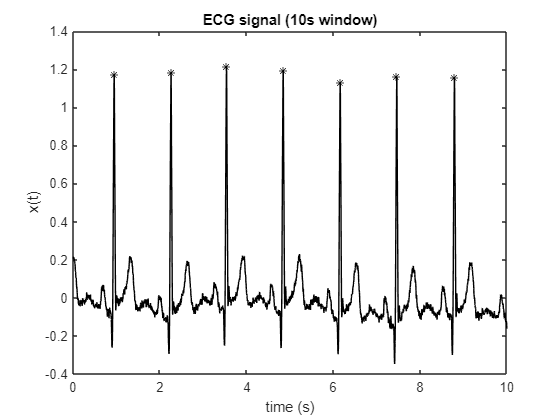

% Extract peaks
[peaks,locations] = findpeaks(data,t,'MinPeakHeight',1); 

% Plot extracted window
figure;
plot(t, data, 'k-'); hold on;
plot(locations, peaks, 'k*');
hold off; 
title('ECG signal (10s window)');
xlabel('time (s)');
ylabel('x(t)');

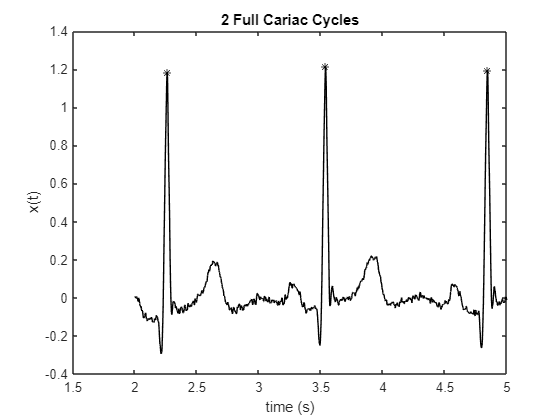


% Consider only 2 full cariac cycles
t = t(2*fs:5*fs);
data = data(2*fs:5*fs);

% Plot 2 full cariac cycles
figure;
plot(t, data, 'k-'); hold on;
plot(locations(2:4), peaks(2:4), 'k*');
hold off; 
title('2 Full Cariac Cycles');
xlabel('time (s)');
ylabel('x(t)');



% Calculate the average heart rate from the 2 full cariac cycles
bpm = (1./mean(diff(locations(2:4)))).*60;
fprintf('Heart rate obtained from the ECG = %.2f bpm',bpm)

Heart rate obtained from the ECG = 46.45 bpm

### Problem: 

Plot ECG signal in the frequency domain.

## Filtering of the ECG for the Removal of the 60 Hz Power-line Artifact

This section is modified from Laboratory Exercises and Projects on Biomedical Signal Analysis, Professor Rangaraj M. Rangayyan, https://people.ucalgary.ca/~ranga/enel563/

A major source of interference in ECG signals is the 60 Hz power-line frequency. The frequency component at 60 Hz can be removed by using a notch filter, in which a zero is placed on the unit circle at the location corresponding to 60 Hz.

- Write a Matlab program to implement the notch filter  with the notch frequency of fo = 60 Hz and the sampling rate of fs = 200 Hz.

- Apply the filter to the signal in the data fileecg_60hz_200.dat. Plot the ECG signal before and after filtering. Study the nature of the artifacts in the noisy signal and in the output of the filter.

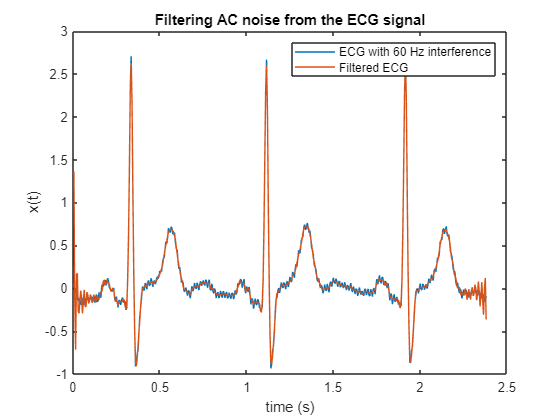

% Given
f0 = 60;
fs = 200;

% ECG Filtering
ecg = load('ecg_60hz_200.dat');
t=[1:length(ecg)]/fs;
ecg_filtered = bandstop(ecg, [55,65],fs);

figure;
plot(t, ecg)
hold on
plot(t, ecg_filtered)
legend(['ECG with 60 Hz interference', "Filtered ECG"]) 
title('Filtering AC noise from the ECG signal');
xlabel('time (s)');
ylabel('x(t)');

%xlim([0.472 0.997])
%ylim([-0.29 0.92])
